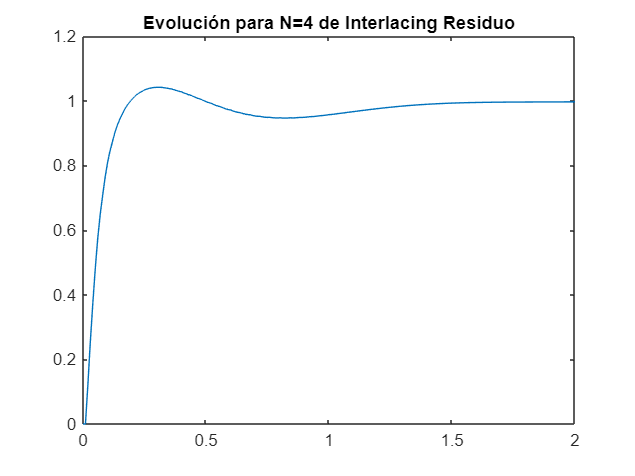

%Representación del interlacing diagonal ordenado por residuo para diferentes N
%El residuo es el criterio que mejor comportamiento presenta

%Los archivos de datos han sido generados en ControlYawN4.mlx a
%ControlYawN8.mlx

clear, close all;

load('DatosN4.mat');%La columna 6 contiene la simulación del interlacing Residuo
Res4=[datos.time,datos.signals.values(:,6)];
RegT=[datos.time,datos.signals.values(:,1:2)];%Ref&Reg_T
figure,plot(Res4(:,1),Res4(:,2)),title('Evolución para N=4 de Interlacing Residuo')

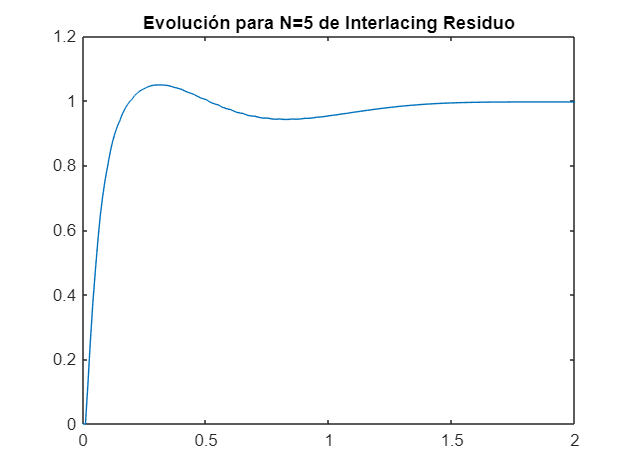

load('DatosN5.mat');%La columna 6 contiene la simulación del interlacing Residuo
Res5=[datos.time,datos.signals.values(:,6)];
figure,plot(Res5(:,1),Res5(:,2)),title('Evolución para N=5 de Interlacing Residuo')

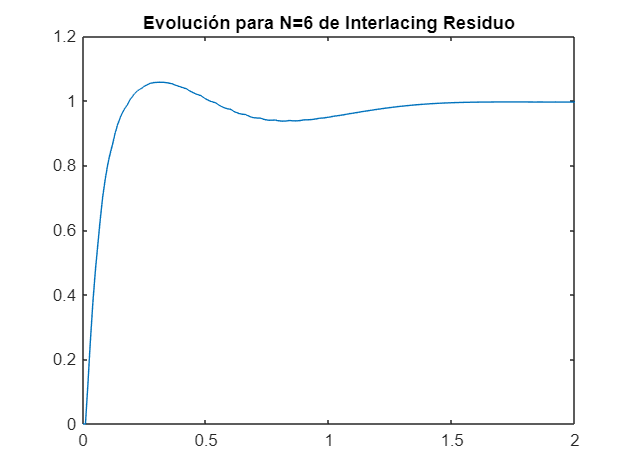

load('DatosN6.mat');%La columna 6 contiene la simulación del interlacing Residuo
Res6=[datos.time,datos.signals.values(:,6)];
figure,plot(Res6(:,1),Res6(:,2)),title('Evolución para N=6 de Interlacing Residuo')

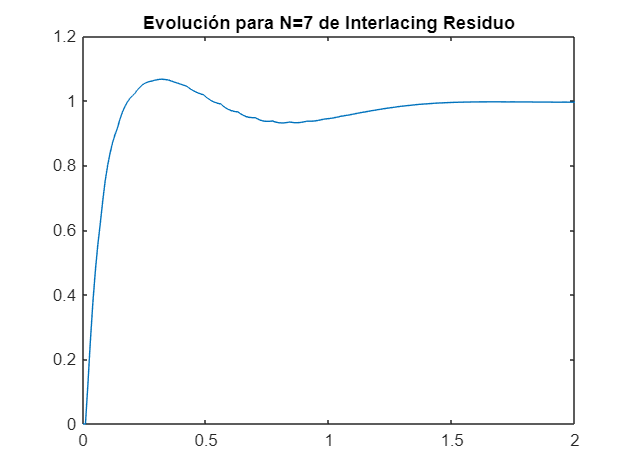

load('DatosN7.mat');%La columna 6 contiene la simulación del interlacing Residuo
Res7=[datos.time,datos.signals.values(:,6)];
figure,plot(Res7(:,1),Res7(:,2)),title('Evolución para N=7 de Interlacing Residuo')

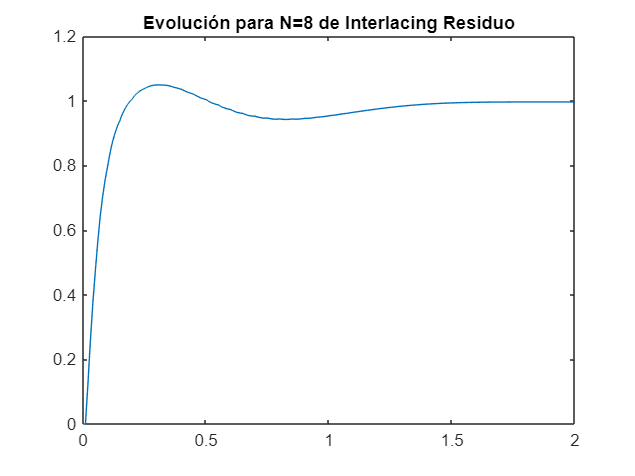

load('DatosN8.mat');%La columna 6 contiene la simulación del interlacing Residuo
Res8=[datos.time,datos.signals.values(:,6)];
figure,plot(Res8(:,1),Res5(:,2)),title('Evolución para N=8 de Interlacing Residuo')

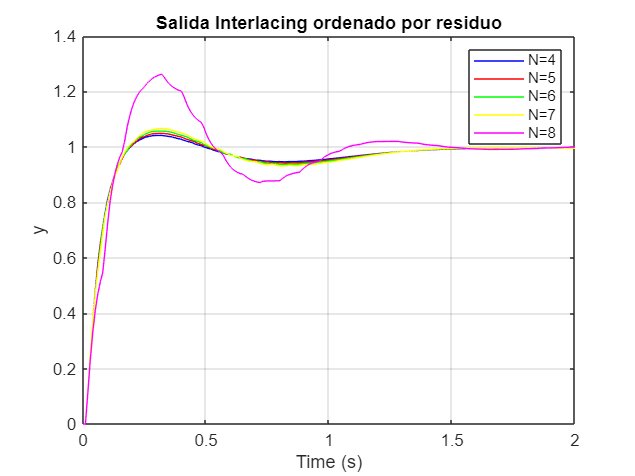

figure;
plot(Res4(:,1),Res4(:,2),'b'),hold on;
plot(Res5(:,1),Res5(:,2),'r');
plot(Res6(:,1),Res6(:,2),'g');
plot(Res7(:,1),Res7(:,2),'y');
plot(Res8(:,1),Res8(:,2),'m');
title('Salida Interlacing ordenado por residuo'), xlabel('Time (s)'), ylabel('y');
legend('N=4','N=5','N=6','N=7','N=8'),grid

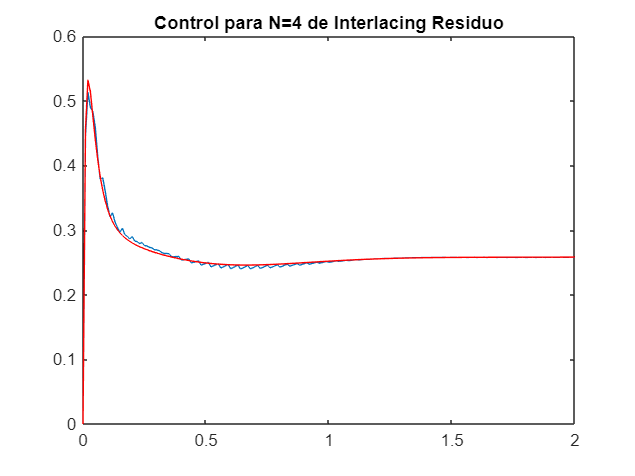


load('ControlN4.mat');%La columna 5 contiene la acción de control del interlacing Residuo
Cont4=[Control.time,Control.signals.values(:,5)];
ContUT=[Control.time,Control.signals.values(:,1)];
figure,plot(Cont4(:,1),Cont4(:,2)),title('Control para N=4 de Interlacing Residuo')
hold on,plot(ContUT(:,1),ContUT(:,2),'r')

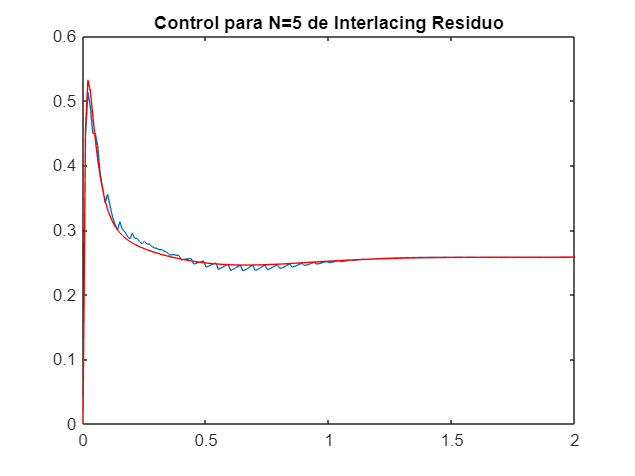

load('ControlN5.mat');%La columna 5 contiene la acción de control del interlacing Residuo
Cont5=[Control.time,Control.signals.values(:,5)];
figure,plot(Cont5(:,1),Cont5(:,2)),title('Control para N=5 de Interlacing Residuo')
hold on,plot(ContUT(:,1),ContUT(:,2),'r')

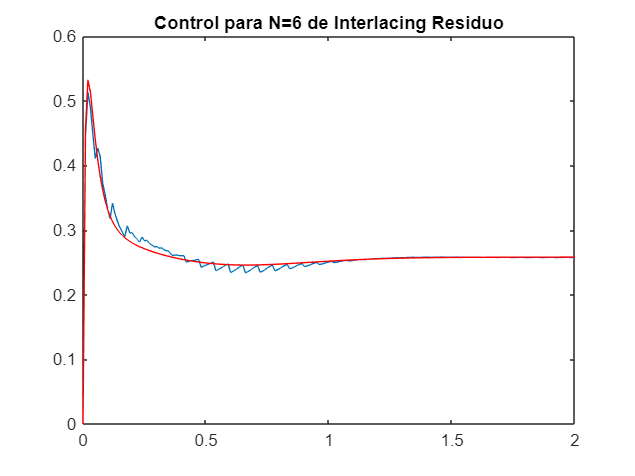

load('ControlN6.mat');%La columna 5 contiene la acción de control del interlacing Residuo
Cont6=[Control.time,Control.signals.values(:,5)];
figure,plot(Cont6(:,1),Cont6(:,2)),title('Control para N=6 de Interlacing Residuo')
hold on,plot(ContUT(:,1),ContUT(:,2),'r')

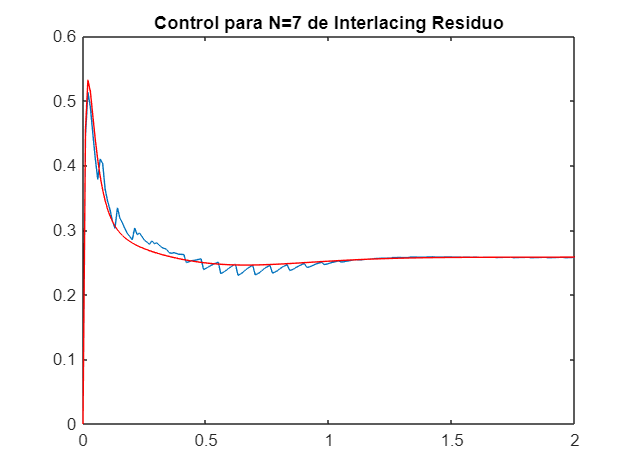

load('ControlN7.mat');%La columna 5 contiene la acción de control del interlacing Residuo
Cont7=[Control.time,Control.signals.values(:,5)];
figure,plot(Cont7(:,1),Cont7(:,2)),title('Control para N=7 de Interlacing Residuo')
hold on,plot(ContUT(:,1),ContUT(:,2),'r')

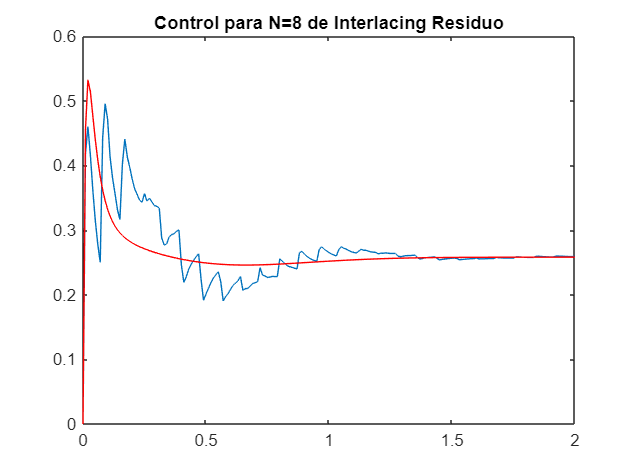

load('ControlN8.mat');%La columna 5 contiene la acción de control del interlacing Residuo
Cont8=[Control.time,Control.signals.values(:,5)];
figure,plot(Cont8(:,1),Cont8(:,2)),title('Control para N=8 de Interlacing Residuo')
hold on,plot(ContUT(:,1),ContUT(:,2),'r')

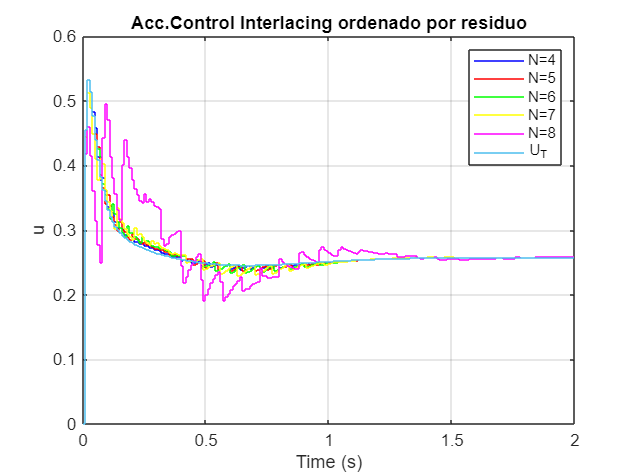



figure;
stairs(Cont4(:,1),Cont4(:,2),'b'),hold on;
stairs(Cont5(:,1),Cont5(:,2),'r');
stairs(Cont6(:,1),Cont6(:,2),'g');
stairs(Cont7(:,1),Cont7(:,2),'y');
stairs(Cont8(:,1),Cont8(:,2),'m');
stairs(ContUT(:,1),ContUT(:,2),'-')
title('Acc.Control Interlacing ordenado por residuo'), xlabel('Time (s)'), ylabel('u');
legend('N=4','N=5','N=6','N=7','N=8','U_T'),grid

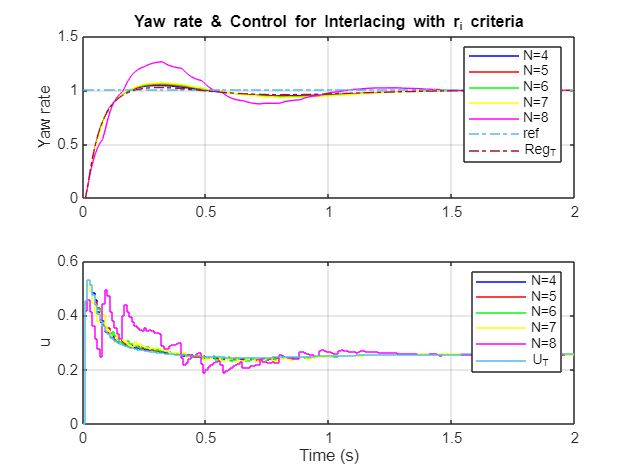


%Salida & Acción control en misma figura
figure;
subplot(211),
plot(Res4(:,1),Res4(:,2),'b'),hold on;
plot(Res5(:,1),Res5(:,2),'r');
plot(Res6(:,1),Res6(:,2),'g');
plot(Res7(:,1),Res7(:,2),'y');
plot(Res8(:,1),Res8(:,2),'m');
plot(RegT(:,1),RegT(:,2:3),'-.')
title('Yaw rate & Control for Interlacing with r_i criteria'), ylabel('Yaw rate');
legend('N=4','N=5','N=6','N=7','N=8','ref','Reg_T'),grid
subplot(212),
stairs(Cont4(:,1),Cont4(:,2),'b'),hold on;
stairs(Cont5(:,1),Cont5(:,2),'r');
stairs(Cont6(:,1),Cont6(:,2),'g');
stairs(Cont7(:,1),Cont7(:,2),'y');
stairs(Cont8(:,1),Cont8(:,2),'m');
stairs(ContUT(:,1),ContUT(:,2),'-')
xlabel('Time (s)'), ylabel('u');
legend('N=4','N=5','N=6','N=7','N=8','U_T'),grid